# Crack Segmentation using Deep Learning

## Data Import Setup

% Classesfor crack detection
classes = ["background","crack"];

% Getting the unique labels from a test image
L = imread("DeepCrack/test_lab/11125-1.png");
unique(L)

ans = 2×1 uint8 column vector
     0
   255


labelIDs = [0 255]; 

dataDir = "DeepCrack";

% Loading Data
trainImgDir = fullfile(dataDir,"train_img");
trainLabDir = fullfile(dataDir,"train_lab");
testImgDir  = fullfile(dataDir,"test_img");
testLabDir  = fullfile(dataDir,"test_lab");

% Training data
imdsTrain = imageDatastore(trainImgDir);
pxdsTrain = pixelLabelDatastore(trainLabDir,classes,labelIDs);
trainingData = pixelLabelImageDatastore(imdsTrain,pxdsTrain);

% Test data
imdsTest = imageDatastore(testImgDir);
pxdsTest = pixelLabelDatastore(testLabDir,classes,labelIDs);
testData = pixelLabelImageDatastore(imdsTest,pxdsTest);


## Understanding the Data

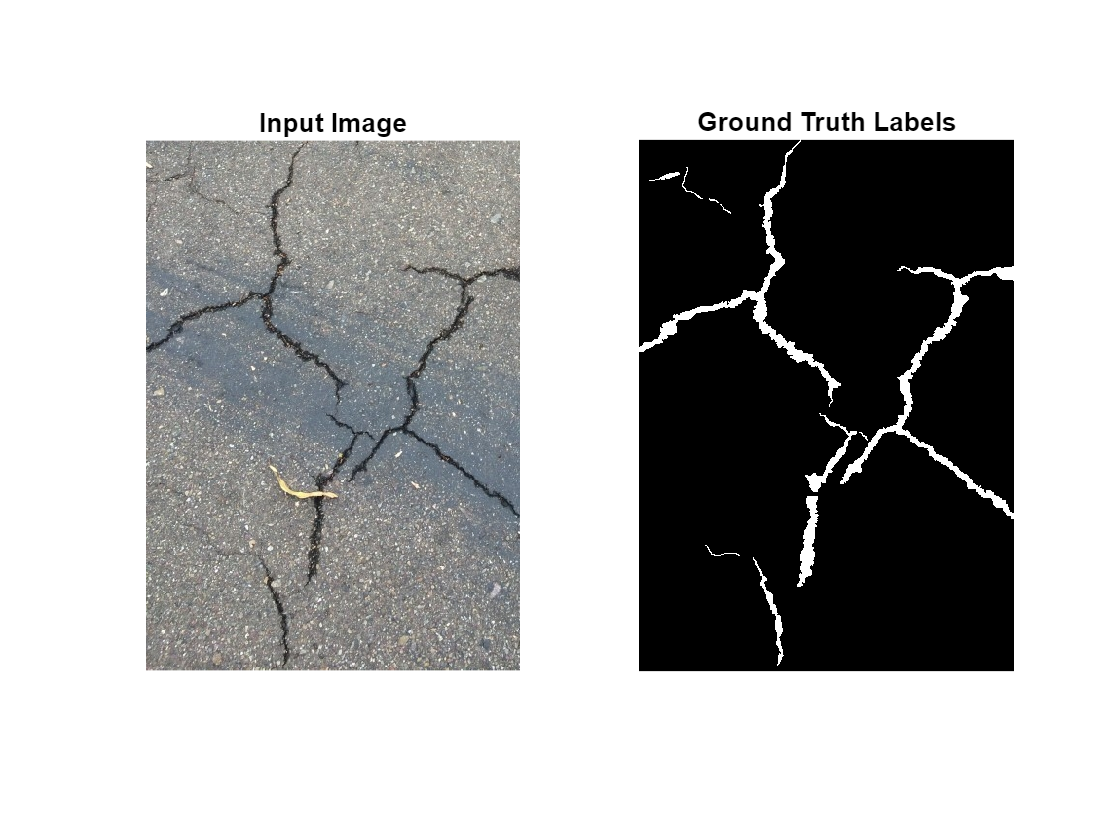

% Pick a sample image and label 
imgFile = fullfile(testImgDir, "11125-1.jpg");   
labFile = fullfile(testLabDir, "11125-1.png");   

% Read the image and label
I = imread(imgFile);
L = imread(labFile);

% Convert label image to numeric 0=background, 1=crack
C_numeric = zeros(size(L), 'like', L);
C_numeric(L == labelIDs(2)) = 1;  % crack = 1

% Plot the RGB image and ground truth (numeric)
figure;
subplot(1,2,1);
imshow(I);
title("Input Image");

subplot(1,2,2);
imshow(C_numeric, []);  % display as grayscale
title("Ground Truth Labels");

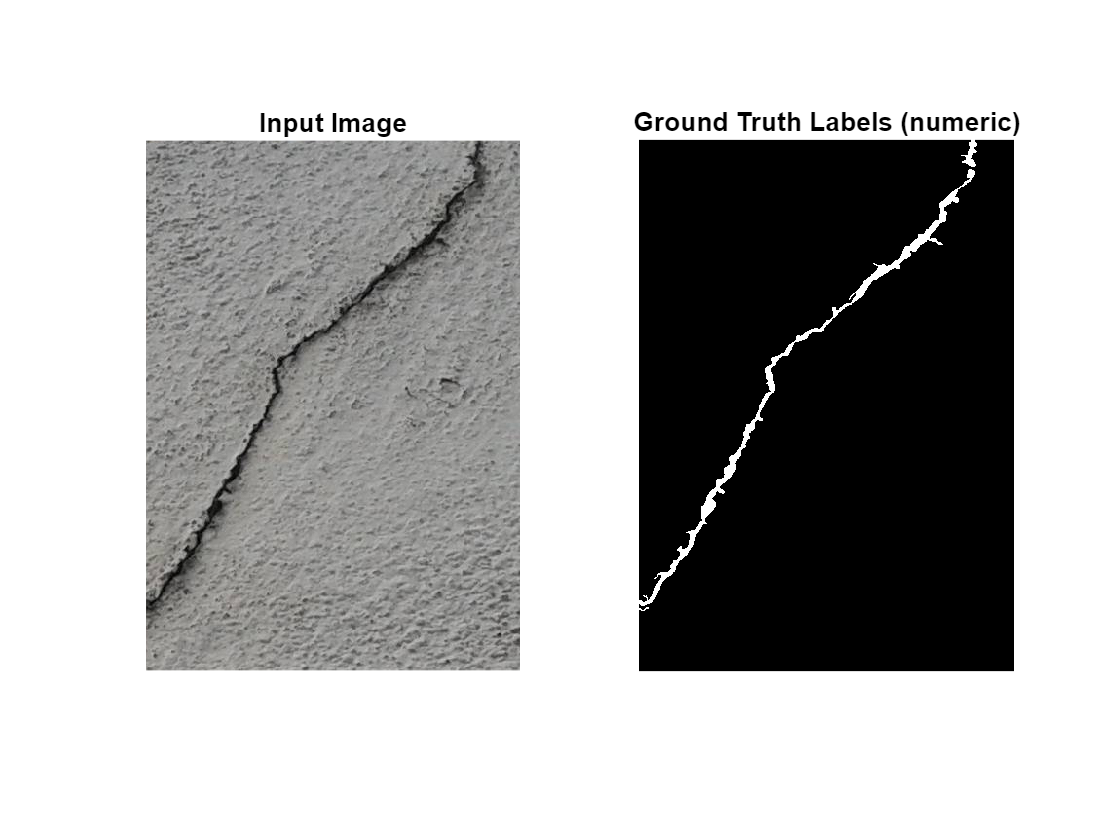

% Read one pair from the datastore
data = read(testData);  

% Extract image and label
I = data.inputImage{1};          
L = data.pixelLabelImage{1};    

% Convert label to numeric for visualization
C_numeric = zeros(size(L), 'uint8');
C_numeric(L == "crack") = 1; 

% Plot the RGB image and ground truth
figure;
subplot(1,2,1);
imshow(I);
title("Input Image");

subplot(1,2,2);
imshow(C_numeric, []);
title("Ground Truth Labels (numeric)");

## Network Structure

% Input image size (resized)
imageSize = [256 256 3];  % RGB images

% Number of classes
numClasses = 2;  % background and crack


% Create U-Net layers
lgraph = unetLayers(imageSize, numClasses);


options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-3, ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 8, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', true);

function dataOut = preprocessData(data, imageSize)
    dataOut = data;
    
    % Extract the image and resize
    img = data.inputImage{1};                  
    dataOut.inputImage = {imresize(img, imageSize(1:2))};  
    
    % Extract the label and resize (nearest)
    lbl = data.pixelLabelImage{1};              % categorical array
    dataOut.pixelLabelImage = {imresize(lbl, imageSize(1:2), 'nearest')};  
end

% Apply preprocessing
trainingData = transform(trainingData, @(data) preprocessData(data, imageSize));
testData = transform(testData, @(data) preprocessData(data, imageSize));

## Train and Store

if isfile('trainedCrackNet.mat')
    % Load existing network
    load('trainedCrackNet.mat', 'net');
else
    % Train the network
    net = trainNetwork(trainingData, lgraph, options);
    
    % Save the network for later use
    save('trainedCrackNet.mat', 'net');
end

## Test on Test Set

if isfile('pxdsPred.mat')
    % Load existing predictions
    load('pxdsPred.mat', 'pxdsPred');
else
    % Compute predictions
    pxdsPred = semanticseg(imdsTest, net, ...
        'MiniBatchSize', 4, ...
        'WriteLocation', tempdir);
    
    % Save predictions
    save('pxdsPred.mat', 'pxdsPred');
end

Running semantic segmentation network
-------------------------------------
* Processed 237 images.



metrics = evaluateSemanticSegmentation(pxdsPred, pxdsTest);

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 237 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.98067          0.82708       0.78801      0.96347        0.84092  




% Accuracy, IoU & F1-score
accuracy = metrics.DataSetMetrics.GlobalAccuracy

accuracy = 0.9807

metrics = metrics.ClassMetrics

metrics = 2×3 table
                  Accuracy      IoU      MeanBFScore
                  ________    _______    ___________

    background    0.99522      0.9801      0.87836  
    crack         0.65894     0.59591      0.80366  


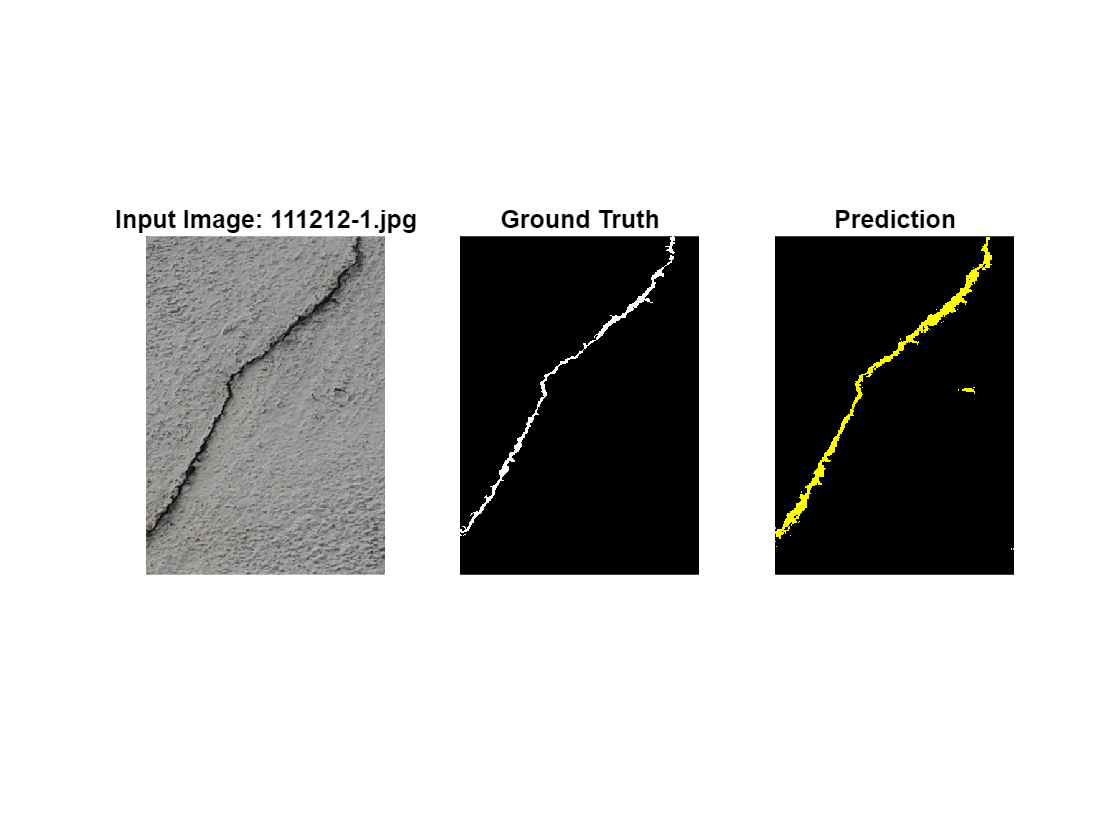

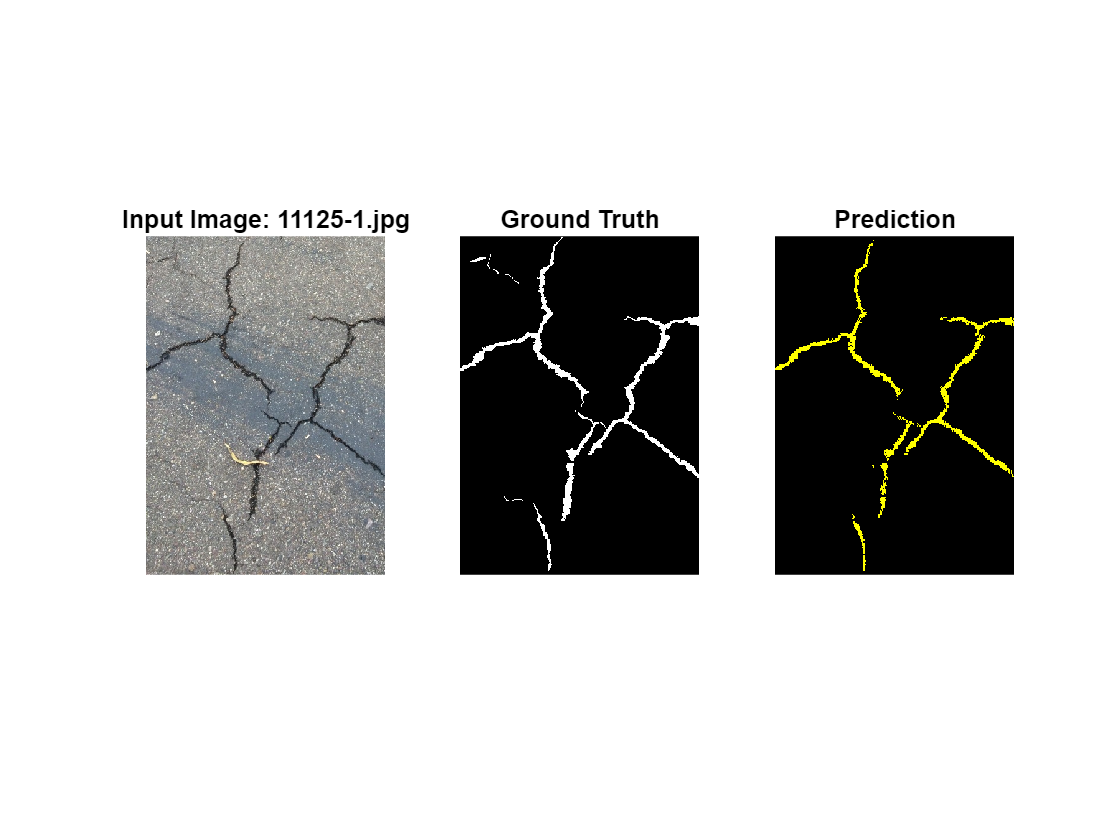

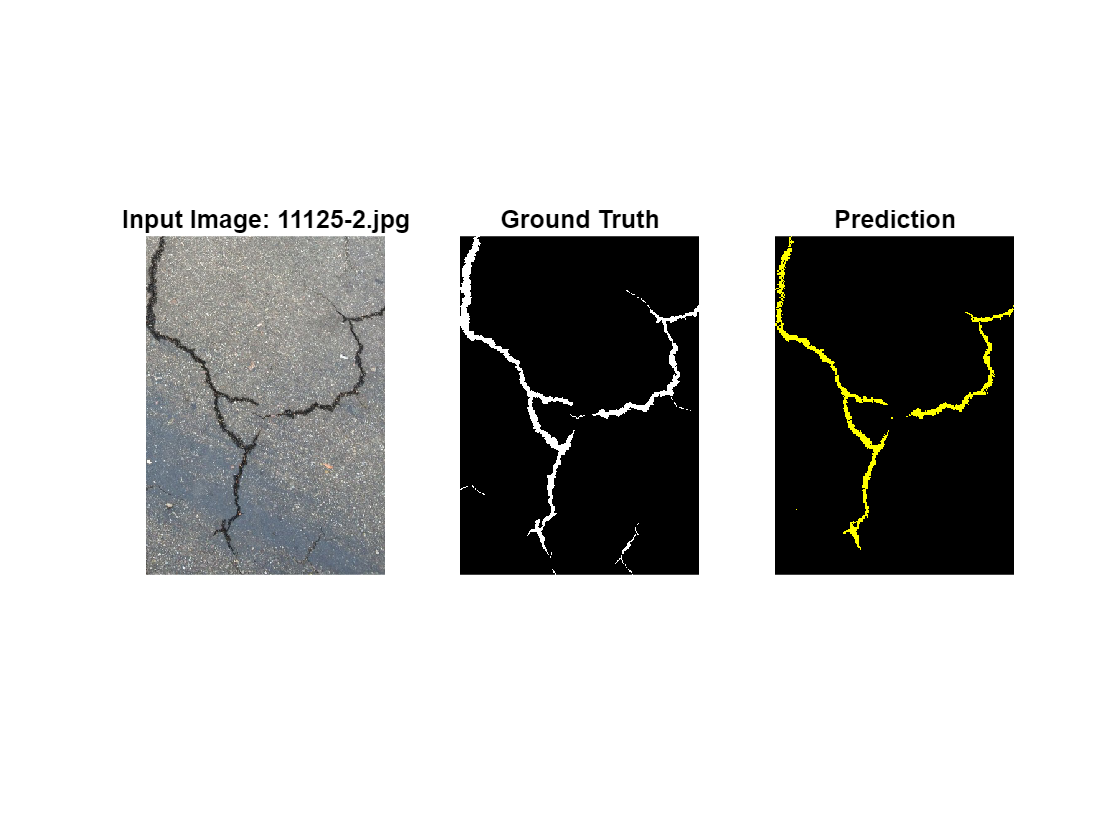


% List Test imgs
imgFiles = dir(fullfile(testImgDir, '*.jpg'));

% Limit to first 3 images 
numImages = min(3, numel(imgFiles));

for k = 1:numImages
    % Get image and corresponding label 
    imgFile = fullfile(testImgDir, imgFiles(k).name);
    
    % Replace extension with .png for label
    [~, name, ~] = fileparts(imgFiles(k).name);
    labFile = fullfile(testLabDir, [name, '.png']);
    
    % Read image and label 
    I = imread(imgFile);
    L = imread(labFile);
    
    % Convert label image to numeric mask
    C_numeric = zeros(size(L), 'like', L);
    C_numeric(L == labelIDs(2)) = 1;  % crack = 1
    
    % Predict segmentation 
    inputSize = net.Layers(1).InputSize(1:2);
    Iresized = imresize(I, inputSize);
    YPred = semanticseg(Iresized, net);
    
    % Resize prediction back to original label size
    YPred_resized = imresize(YPred, [size(L,1) size(L,2)], 'nearest');
    
    % Convert prediction to numeric mask
    P_numeric = zeros(size(YPred_resized), 'uint8');
    P_numeric(YPred_resized == "crack") = 1;
    
    % Create yellow RGB overlay for prediction
    predRGB = zeros([size(P_numeric), 3], 'uint8');
    predRGB(:,:,1) = P_numeric * 255;  % Red
    predRGB(:,:,2) = P_numeric * 255;  % Green
    predRGB(:,:,3) = 0;                % Blue
    
    % Plot input, ground truth, prediction 
    figure;
    subplot(1,3,1);
    imshow(I);
    title("Input Image: " + name + ".jpg");
    
    subplot(1,3,2);
    imshow(C_numeric, []);
    title("Ground Truth");
    
    subplot(1,3,3);
    imshow(predRGB);
    title("Prediction");
end